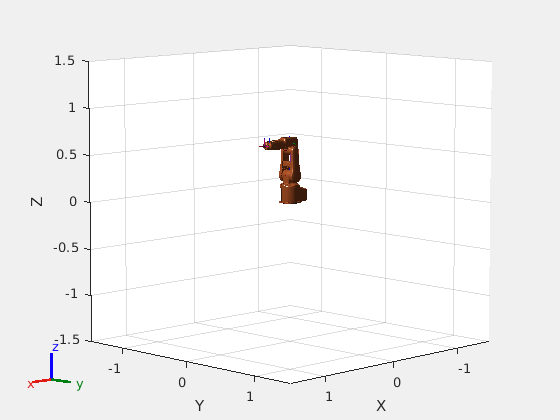

robot = loadrobot("abbIrb120");
show(robot);

config = robot.homeConfiguration;
config(1).JointPosition = -0.29983205;
config(2).JointPosition = -0.39576897;
config(3).JointPosition = 0.38292384;
config(4).JointPosition = 0.00329983;
config(5).JointPosition = 0.1237199;
config(6).JointPosition = -0.01486687;

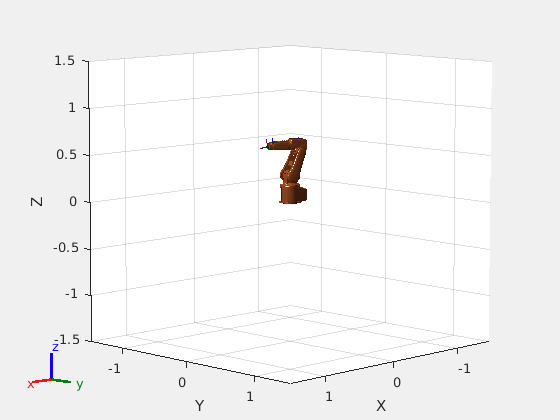

show(robot,config);

newpose = getTransform(robot,config,"link_6");
disp('POSE by joint angles for neural network:')

POSE by joint angles for neural network:


disp(newpose(1,4));

    0.2566



disp(newpose(2,4));

   -0.0793



disp(newpose(3,4));

    0.6050



### ACTUAL KINEMATICS

pos = [0.2583 -0.0764  0.608];
posvec = trvec2tform(pos);
disp(posvec);

    1.0000         0         0    0.2583
         0    1.0000         0   -0.0764
         0         0    1.0000    0.6080
         0         0         0    1.0000




ik = inverseKinematics("RigidBodyTree",robot);
weights = [0 0 0 1 1 1];
initialguess = homeConfiguration(robot);

[configSoln,solnInfo] = ik("link_6",posvec,weights,initialguess);

disp(configSoln);

  1×6 struct array with fields:

    JointName
    JointPosition



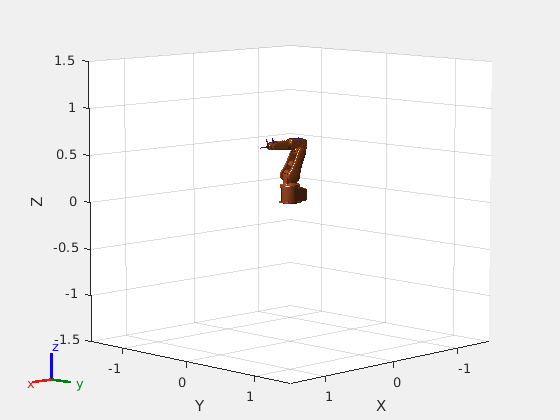

show(robot,configSoln);